% inputs 
% corresponding weights
% summation
% given to activation block
%1.	Write a user defined function for threshold activation function using Matlab and python

clc

 1 = tanh \n 2 = sigmoid \n 3 = threshold


c = 4

clear 

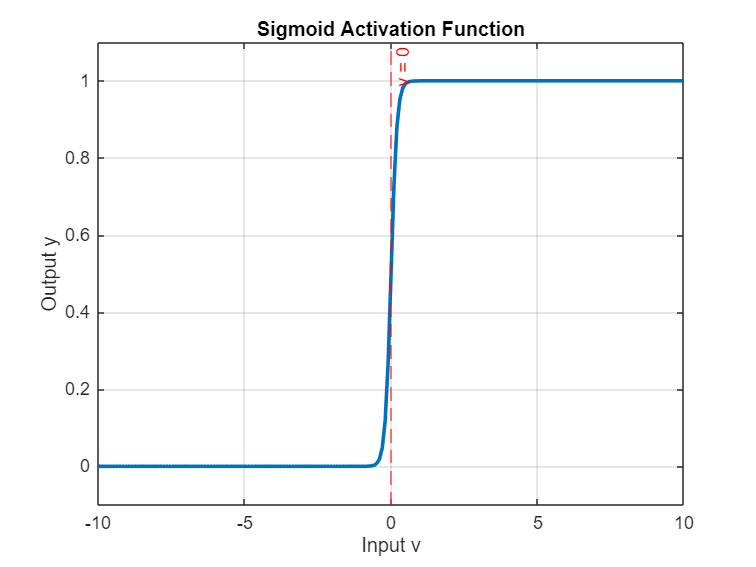

disp (' 1 = tanh \n 2 = sigmoid \n 3 = threshold')

c= input('Enter a choice: ')


n = input('Enter the size of the vector: ');


w = rand(n, 1);

%inputs
% Initialize vector
x = zeros(n, 1);   

% Loop to get each element
for i = 1:n
    x(i) = input(sprintf('Enter element %d: ', i));
end


s = sum(w .* x)


switch c
    case 1
        y = tanh_func(s);
    case 2
        a = rand
        y = sigmoid_func(a, s);
    case 3
        y = threshold_func(s);
    otherwise
        disp('Unknown signal.');
end


% Define functions below (after your main code or in separate .m files)

function y = tanh_func(v)
    y = (exp(v) - exp(-v)) ./ (exp(v) + exp(-v));
end

function y = sigmoid_func(a, v)
    y = 1 ./ (1 + exp(-a * v));
end

function y = threshold_func(v)
    y = double(v >= 0);
end

fprintf('Result after activation: %.4f\n', y);

msg = sprintf('Result after activation: %.4f\n', y);
disp(msg);

% Define a range of input values
v_range = -10:0.1:10;

% Define slope parameter
a = 10;

% Compute the sigmoid output over the range
y_range = sigmoid_func(a, v_range);

% Plot the result
figure;
plot(v_range, y_range, 'LineWidth', 2);
grid on;
xlabel('Input v');
ylabel('Output y');
title('Sigmoid Activation Function');
ylim([-0.1 1.1]);
xline(0, '--r', 'v = 0');  % Optional: vertical threshold line